# Part 1

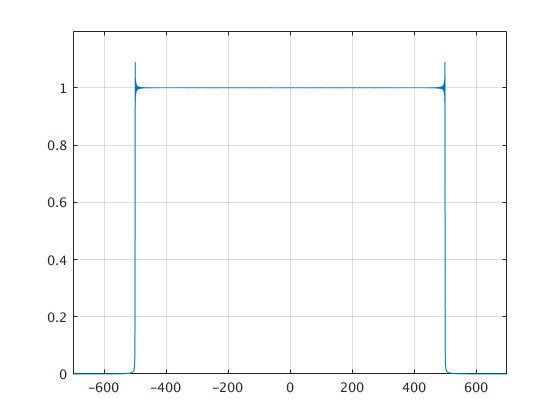

clear;clc
fs = 20000;
T = 1/fs;
L = 20000;
t = (-L:L-1)*T;

mt=1000*sinc(t*1000);

plot_fft(fs, L, mt);
xlim([-700 700]);

# Part 2

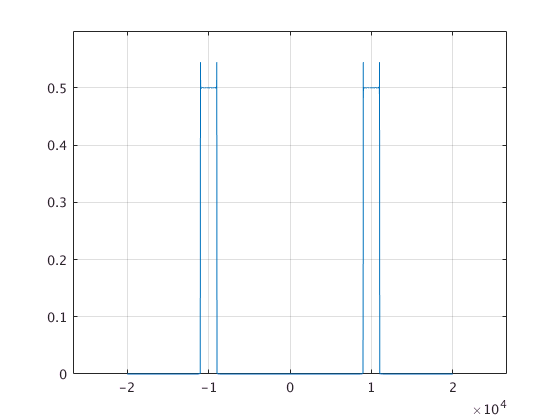


fc = 10000;
fs = 40000;            % 采样频率
T = 1/fs;             % 采样周期
L = 20000;             % 信号长度   由此知，频率分辨率为 1hz
t = (-L:L-1)*T;        % 时间相量

ut=ammod(mt,fc,fs);
plot_fft(fs, L, ut);

# Part 3

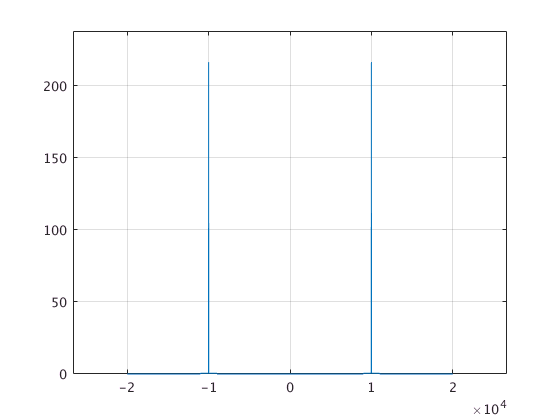

% Ac_min = min(mt)
Ac_min = min(mt);
amt = Ac_min + mt;
uat=ammod(amt,fc,fs);
plot_fft(fs, L, uat);

# Part 4

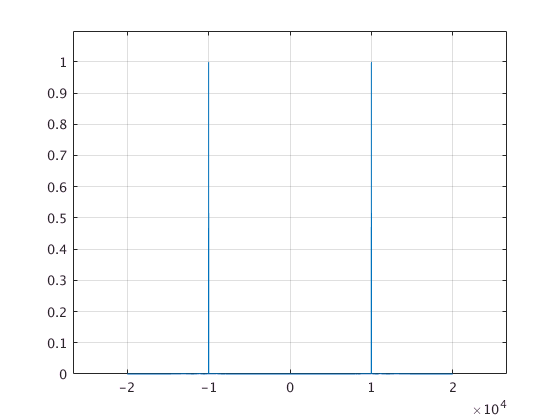

fdev = 4;
vt=fmmod(mt,fc,fs,fdev);
plot_fft(fs, L, vt);

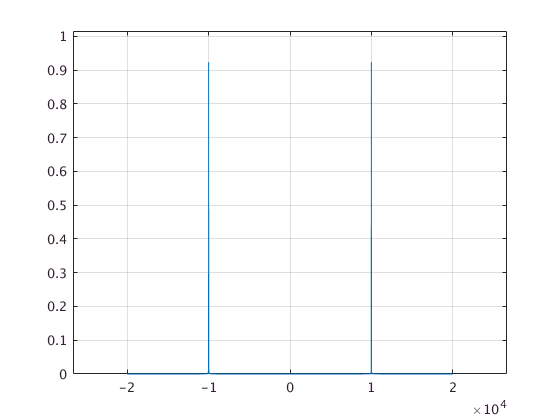

fdev = 1/4;
vt=fmmod(mt,fc,fs,fdev);
plot_fft(fs, L, vt);

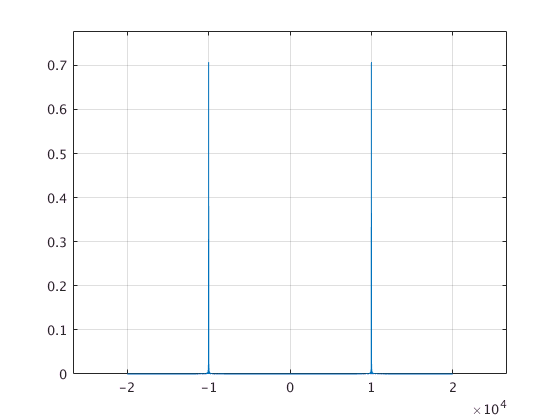

fdev = 1/2;
vt=fmmod(mt,fc,fs,fdev);
plot_fft(fs, L, vt);